# Compute the degrees of freedom using the Twomey/Platnick method

Andrew John Buggee

## Introduction

I know two ways to determine the number of unique pieces of information afforded by measurements. The first was outline by Rodgers (1996). Using a Bayesian framework, Rodgers defines the number of degrees of freedom by computing the trace of an averaging kernel matrix, which has dimensions $n \, x \, n$ where $n$ is the number of state variables. This method is easy to compute when using the Gauss-Newton optimal estimation method to retrieve a state vector, but it is limited by the number of state variables the retrieval was designed to estimate. In addition, it seems to me that the bayesian framework also depends on the strength of the prior distribution. 

Platnick's method does not require a predetermination of the number of state variables you'd like to retreive. Instead, it uses weighting functions to determine the instrinsic information content avaiable in the measurements. So, whereas the Rodger's framework leads to determine whether the number of desired state variables is reasonable, Platnick's method sets a limit of the number of varaibles that can be determined.

## The Matematics

## Compute the number of unique pieces of information

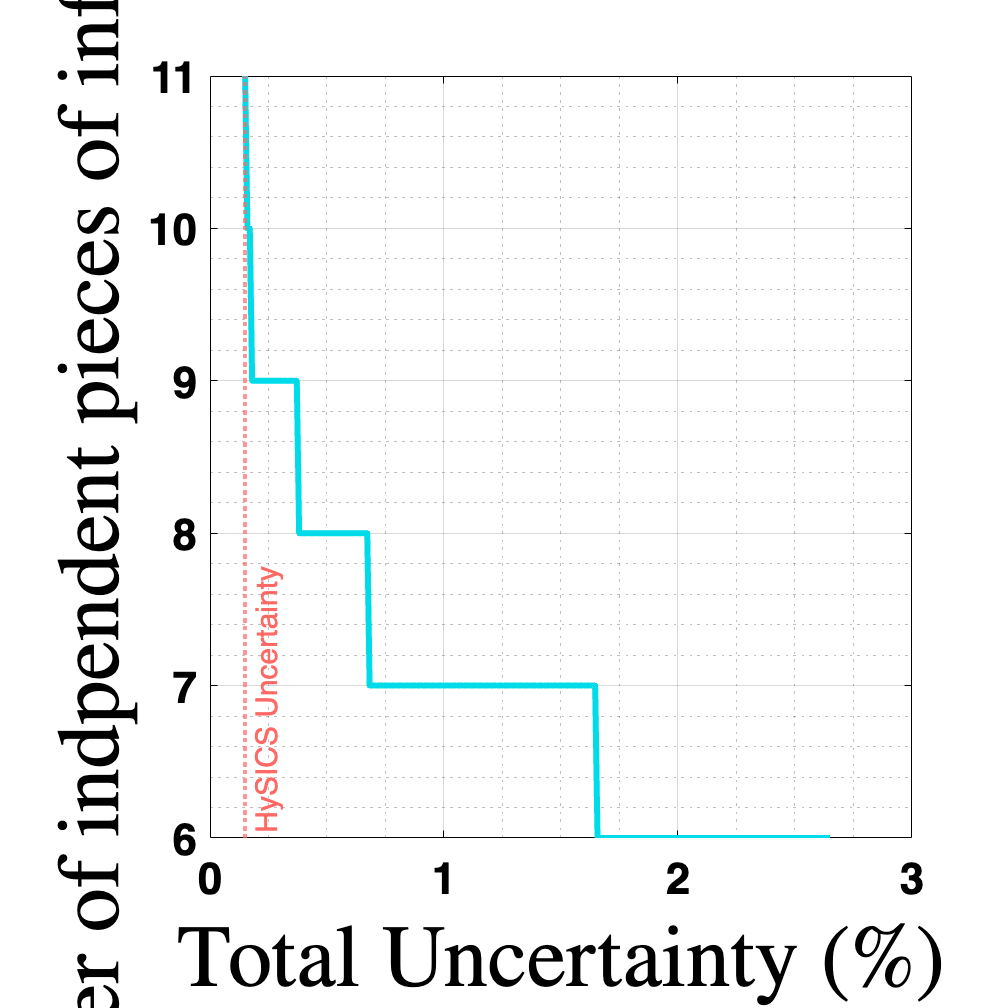

% First, load a set of weighting functions

clear variables

make_plot = false;

if strcmp(whatComputer, 'andrewbuggee')==true


    % All 636 HySICS wavelenghts with an adiabatic profile
    % r_top = 12     r_bot = 5    tau_c = 8
    load(['/Users/andrewbuggee/Documents/MATLAB/Matlab-Research/',...
        'Hyperspectral_Cloud_Retrievals/HySICS/weighting_functions/',...
        'disort_HySICS_reflectance_for_weightingFunctions_allBands_adiabatic_droplet_profile_sim-ran-on-07-Apr-2026_rev1.mat']);

    % All 636 HySICS wavelenghts with an adiabatic profile
    % r_top = 9     r_bot = 5    tau_c = 8
    % load(['/Users/andrewbuggee/Documents/MATLAB/Matlab-Research/',...
    %     'Hyperspectral_Cloud_Retrievals/HySICS/weighting_functions/',...
    %     'disort_HySICS_reflectance_for_weightingFunctions_inhomogeneous_droplet_profile_sim-ran-on-08-Apr-2026_rev1.mat']);

    % All 636 HySICS wavelenghts with an adiabatic profile
    % r_top = 12     r_bot = 5    tau_c = 24
    % load(['/Users/andrewbuggee/Documents/MATLAB/Matlab-Research/',...
    %     'Hyperspectral_Cloud_Retrievals/HySICS/weighting_functions/',...
    %       'disort_HySICS_reflectance_for_weightingFunctions_inhomogeneous_droplet_profile_sim-ran-on-08-Apr-2026_rev2.mat'])

    % All 636 HySICS wavelenghts with an adiabatic profile
    % r_top = 12     r_bot = 5    tau_c = 4
    % load(['/Users/andrewbuggee/Documents/MATLAB/Matlab-Research/',...
    %     'Hyperspectral_Cloud_Retrievals/HySICS/weighting_functions/',...
    %       'disort_HySICS_reflectance_for_weightingFunctions_inhomogeneous_droplet_profile_sim-ran-on-09-Apr-2026_rev1.mat'])

end




% ---------------------------------------------------------------------
% ---------------------------------------------------------------------
% plot the weighting function(s)

if make_plot == true
    % *** define which wavelengths to plot ***
    wl_2plot = mean(inputs.RT.wavelengths2run(10,:), 2);

    lgnd_str = cell(numel(wl_2plot), 1);

    figure;


    if inputs.RT.monochromatic_calc==true

        for ww = 1:length(wl_2plot)

            [~,idx2plot] = min(abs(inputs.RT.wavelengths2run(:,1) - wl_2plot(ww)));

            % Plot the tau mid-point of each layer
            plot(w(:,idx2plot), tau_midPoint, 'Color', mySavedColors(ww, 'fixed'))


            hold on
            plot(f(:,idx2plot), tau_midPoint, 'Color', mySavedColors(ww, 'fixed'), 'LineStyle', ':')

            lgnd_str{ww} = ['$\lambda = $', num2str(round(inputs.RT.wavelengths2run(idx2plot, 1), 1)), ' $nm$'];

        end



    else

        tau = changing_variables(2:end,3);

        % plot(w, diff(flipud(changing_variables(:,2)))/2 + flipud(changing_variables(2:end,2)))
        plot(w, flipud(tau))

        % --- overlay a smoothed spline fit ---
        % Create smooth spline function
        % f=fit(diff(flipud(changing_variables(:,2)))/2 + flipud(tau), w, 'smoothingspline','SmoothingParam',0.95);
        f = movmean(w, N_mov_avg);

    end


    % Set up axes labels
    set(gca, 'YDir','reverse')
    grid on; grid minor
    xlabel('$w(\tau)$','Interpreter','latex');
    ylabel('$\tau$','Interpreter','latex')

    % Create title
    % title(['Weighting Function at ', num2str(changing_variables(1,1)), ' nm'],'Interpreter','latex')
    title('Weighting Functions for HySICS','Interpreter','latex')


    set(gcf, 'Position',[0 0 1400 800])


    % Create Legend
    % legend(string(inputs.RT.wavelengths2run(:,1))','Interpreter','latex','Location','northwest','FontSize',22)
    legend(lgnd_str,'Interpreter','latex','Location','northwest','FontSize',22)

    % Create textbox with simulation properties

    % Textbox
    dim = [0.155714285714286 0.144548492431641 0.196462309701102 0.382951507568359];

    if ischar(inputs.RT.sensor_altitude)==true
        texBox_str = {['N layers = ', num2str(inputs.RT.n_layers)],...
            ['$sza$ = ',num2str(inputs.RT.sza)],...
            ['$vza$ = ',num2str(inputs.RT.vza)],...
            ['$z_{out}$ = ', inputs.RT.sensor_altitude],...
            ['$Cloud\;top$ = ', num2str(inputs.RT.z_topBottom(1)), ' km'],...
            ['$Cloud\;base$ = ', num2str(inputs.RT.z_topBottom(2)), ' km'],...
            ['$r_{top}$ = ',num2str(round(inputs.RT.r_top)), ' $\mu m$'],...
            ['$r_{bot}$ = ',num2str(round(inputs.RT.r_bot)), ' $\mu m$'],...
            ['$\tau_0$ = ', num2str(inputs.RT.tau_c)],...
            ['$A_0$ = ', num2str(inputs.RT.surface_albedo)]};
    else
        texBox_str = {['N layers = ', num2str(inputs.RT.n_layers)],...
            ['$sza$ = ',num2str(inputs.RT.sza)],...
            ['$vza$ = ',num2str(inputs.RT.vza)],...
            ['$z_{out}$ = ', num2str(inputs.RT.sensor_altitude), ' km'],...
            ['$Cloud\;top$ = ', num2str(inputs.RT.z_topBottom(1)), ' km'],...
            ['$Cloud\;base$ = ', num2str(inputs.RT.z_topBottom(2)), ' km'],...
            ['$r_{top}$ = ',num2str(round(inputs.RT.r_top)), ' $\mu m$'],...
            ['$r_{bot}$ = ',num2str(round(inputs.RT.r_bot)), ' $\mu m$'],...
            ['$\tau_0$ = ', num2str(inputs.RT.tau_c)],...
            ['$A_0$ = ', num2str(inputs.RT.surface_albedo)]};
    end

    t = annotation('textbox',dim,'string',texBox_str,'Interpreter','latex');
    t.Color = 'black';
    t.FontSize = 25;
    t.FontWeight = 'bold';
    t.EdgeColor = 'black';
    t.FitBoxToText = 'on';

    xlim([0.0388 0.1265])
    ylim([1.29 6.30])
end
% ---------------------------------------------------------------------
% ---------------------------------------------------------------------






% Next, construct the covariance matrix defined by Platnick (2000)


% recreate the droplet profile used to create the weighting functions
re = create_droplet_profile2([inputs.RT.r_top, inputs.RT.r_bot],...
    linspace(inputs.RT.z_topBottom(2), inputs.RT.z_topBottom(1), length(tau_2run)),...
    inputs.RT.indVar, inputs.RT.profile_type);     % microns - effective radius vector

% The re vector moves from bottom to top. Flip it so it moves from top to
% bottom, and find the midpoint of each layer.
re_midPoint = flipud(re(1:end-1) + diff(re)/2);




% step through each weighting function and compute the estimated
% single band effective radius retrieval (Platnick (2000), eq. 3)
re_est = zeros(1, size(f,2));

for ww = 1:size(f,2)

    re_est(ww) = trapz(tau_midPoint, re_midPoint .* f(:,ww));

end


% The elements of this symmetric matrix are given by the inner product of
% the weightings (Platnick (2000) pg. 22933)

C = zeros(size(inputs.RT.wavelengths2run,1), size(inputs.RT.wavelengths2run,1));

% this matrix is symmetric, meaning C(1,3) = C(3,1).

% Normalize the covariance matrix by the two effective radii estimates for
% the ith and jth element

for ii = 1:size(inputs.RT.wavelengths2run,1)
    for jj = 1:size(inputs.RT.wavelengths2run,1)

        C(ii,jj) = trapz(tau_midPoint, (f(:,ii) .* f(:,jj)) / (re_est(ii)*re_est(jj)) );

    end
end


% compute the eigenvalues of our scaled covariance matrix
eig_val = eig(C);


% According to Platnick (2000): "Then for all weightings to contribute unique
% information,the minimum eigenvalue of the scaled covariance matrix must be
% greater than about e^2/(N r_m^2), where N is the number of measurements,
% r_m is the mean value of the unknown re(tau) profile, and e is the relative
% uncertainty of the retrieval and the weighting function (forward model uncertainty)
% [Twomey, 1977]

% The relative uncertainty is the sum of the measurement uncertainty of the
% instrument and the forward model unceratinty of the weighting functions
uncert_hysics = 0.003;                    % 0.3% radiometric uncertainty for all HySICS wavelengths
uncert_fm = linspace(0, 0.05, 250);       % Forward model uncertainty of 4%
relative_uncert = uncert_hysics + uncert_fm;

twomey_fraction = relative_uncert.^2 ./ (size(w,2) * mean(re)^2);


num_eV_exceeds_threshold = eig_val > twomey_fraction;

if length(uncert_fm) < 5
    disp([newline, 'The number of unique pieces of information is ',...
        num2str(sum(num_eV_exceeds_threshold)), newline])
else
    
    % Set the height and width as multiples of the IEEE paper requirements
    w = 3.5; % inches
    h = 3.5;    % inches

    figure1 =     figure;
    figure1.Units = 'inches';    
    figure1.Position = [1, 1, 2*w, 2*h]; % [left, bottom, width, height]

    plot(relative_uncert .* 100, sum(num_eV_exceeds_threshold, 1),...
        'Color', mySavedColors(70, 'fixed'), 'LineWidth', 3)
    xlabel('Total Uncertainty (\%)', 'Interpreter', 'latex',...
        'FontSize', 20)
    ylabel('Number of indpendent pieces of information', 'Interpreter', 'latex',...
        'FontSize', 20)
    grid on; grid minor
    hold on;
    xline(100*uncert_hysics, ':', 'Label','HySICS Uncertainty', 'Color',...
        mySavedColors(72, 'fixed'), 'FontSize', 15, 'LineWidth', 2,...
        'LabelVerticalAlignment','bottom')
    % update x-axis tick labels
    xticks([0, 1, 2, 3, 4, 5])
    xticklabels({'0', '1', '2', '3', '4', '5'})

    % ** Paper Worthy **
    % -------------------------------------
    % ---------- Save figure --------------
    % save .fig file
    if strcmp(whatComputer,'anbu8374')==true
        error(['Where do I save the figure?'])
    elseif strcmp(whatComputer,'andrewbuggee')==true
        folderpath_figs = '/Users/andrewbuggee/Documents/MATLAB/Matlab-Research/Presentations_and_Papers/paper_3/saved_figures/';
    end
    saveas(figure1,[folderpath_figs,'Number of independent pieces of information vs total uncertainty.fig']);


    % save .png with 500 DPI resolution
    % remove title
    title('');
    exportgraphics(figure1,[folderpath_figs,'Number of independent pieces of information vs total uncertainty.png'],...
        'Resolution', 500);
    % -------------------------------------
    % -------------------------------------

end

## Plot all estimated effective radius retrievals

figure;

plot(re_midPoint, tau_midPoint)
hold on; grid on; grid minor
tau_est = zeros(size(re_midPoint));

for nn = 1:length(re_est)
    [~, re_idx] = min(abs(re_est(nn) - re_midPoint));
    tau_est(nn) = tau_midPoint(re_idx);

    % yline(tau_est, 'Color', 'k', 'LineWidth',1)
end

hold on;
plot(re_est, tau_est, '.', 'MarkerSize', 20)
set(gca, 'YDir','reverse')
xlabel('$r_{e} \, (\mu m)$','Interpreter','latex');
ylabel('$\tau$','Interpreter','latex')



